YFP1: PCNA stain

FarRed1: EdU stain

POI(:,2) : time of APC/C inactivation

[file_loc] = fileparts(matlab.desktop.editor.getActiveFilename);
cd(file_loc);
dataDir = 'F:\Data\C-Cdt1\Figures\Dryad\Data\';
impath = fullfile(dataDir,'C184_images',filesep);
%%% Experiment Paremeters %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
conditions = {
%    'dox+',2,2,1:4,[0 0 0]; %1    
         'dox+',2:5,2:11,1:4,[0 0 0]; %1    
         'dox-',6,2:11,1:4,[0 0 0]; %1 
        

    };


load([dataDir filesep 'C184_data.mat'],'S')
% S = loadData(conditions, dataDir);
framesPerHr = 60/10;
frameDrugAdded = 0;                                                  
frameEdU = 0;
folding = 0;

numFrames = size(S(1).area,2);
xFrames = 1:numFrames;
xTime = (xFrames-1)./framesPerHr;

## **View  tr****aces**** to check properties**

conds = [1 2];
for i=1:length(conds)
%inds = ~S(conds(i)).apcBadTraces;
inds = true(size(S(conds(i)).area(:,1)));
cells = find(inds);
nums = randsample(cells,100);
figure,
subplot(2,1,1), plot(S(conds(i)).apcNuc(nums,:)')
ylabel('APC sensor intensity')
ylim([0 100])
title(conditions(conds(i),1));
subplot(2,1,2), plot((S(conds(i)).sigNuc(nums,:))')
ylabel('CRL4 sensor intensity')
%ylim([0 1])
end

Traces look okay overall

**Gate sig POI expression**

for i = 1:length(S)
    data = S(i).sigNuc;
    S(i).sigMax = NaN*ones(size(data(:,end)));
    for j = 1:size(data,1)
        if ~isnan(S(i).POI(j,3))
            S(i).sigMax(j) = data(j,S(i).POI(j,3));
        end
    end
end

**Set thresholds based on G1 for costain**

cond = 1;
figure
xval = 'FarRed';
yval = 'YFP';

xdata = log2(S(cond).(xval));
ydata = log2(S(cond).(yval));


inds = log2(S(cond).dna) < 22   & S(cond).dna > 2^21 &...
    isnan(S(cond).POI(:,3)) & isnan(S(cond).POI(:,2)) & S(cond).FarRed < 2^8.5 & S(cond).YFP < 2^9 ;
xdata = xdata(inds);
ydata = ydata(inds);

inds = xdata < prctile(xdata,99) & ydata < prctile(ydata,99);
xdata = xdata(inds);
ydata = ydata(inds);

EdUThresh = prctile(xdata,[50 99])

EdUThresh =     5.9071    6.8941


PCNAThresh = prctile(ydata,[50 99])

PCNAThresh =     6.3923    7.7469


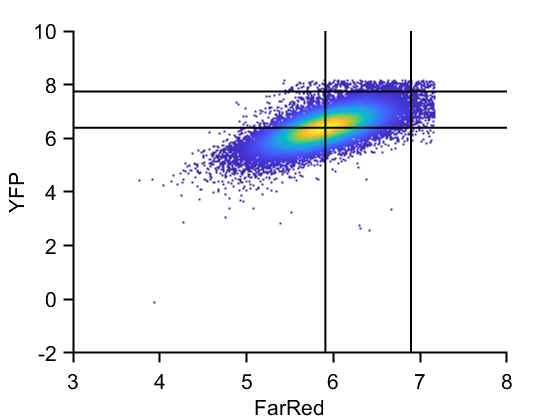



dscatter(xdata,ydata)
hline(PCNAThresh,'k');
vline(EdUThresh,'k');
ylabel(yval);xlabel(xval);

Settings thresholds based on 97% (with a removal of EdU positive cells by arb threshold)

## **Plot traces aligned**

ans = 7059

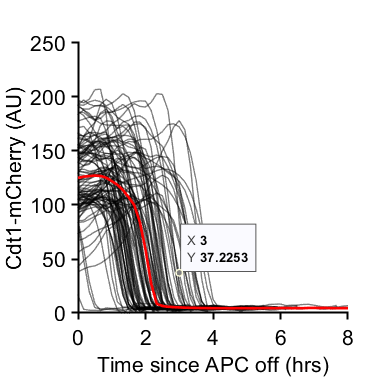

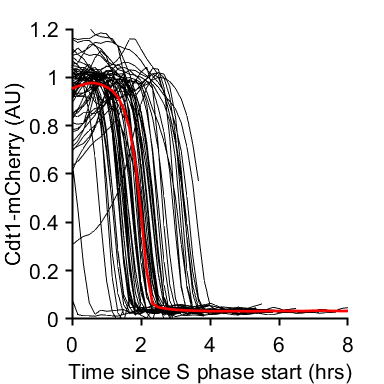

rng(6)

conds=[1];
poiAlign = [2];
alignNames = {'APC off','CRL4 on'};
for p = 1:length(poiAlign)
    figure('Units', 'Inches', 'Position', [0, 0, 4, 4]);
    hold on
    for i=1:length(conds)
        inds = ~isnan(S(conds(i)).POI(:,poiAlign(p))) &...
            S(conds(i)).sigMax > 100 & S(conds(i)).sigMax <200 & ...
            S(conds(i)).YFP > 2^PCNAThresh(2);
        cells = find(inds);
        length(cells)
        for numcell = randsample(cells,min([100 length(cells)]))'
            timeAligned = (xFrames-S(conds(i)).POI(numcell,poiAlign(p)))/framesPerHr;
            patchline(timeAligned,nansmoothm(S(conds(i)).sigNuc(numcell,:),5,'sgolay'),'edgecolor','k','linewidth',1,'edgealpha',.5);
            ylabel('Cdt1-mCherry (AU)');
            xlabel('Time since APC off (hrs)');
            ylim([0 250]);
            xlim([0 8]);
            axis square
        end
        [frames, medSig, semCRL] =get_median_trace(S(conds(i)).sigNuc(cells,:),S(conds(i)).POI(cells,poiAlign(p)),0);
        plot((frames)/framesPerHr,medSig,'k','LineWidth',2,'Color','r')
        
    end
    hold off
   print_pdf([pwd() '\Figs\traces_' num2str(conds(i)) '.pdf'])

end

## **Plot example traces**

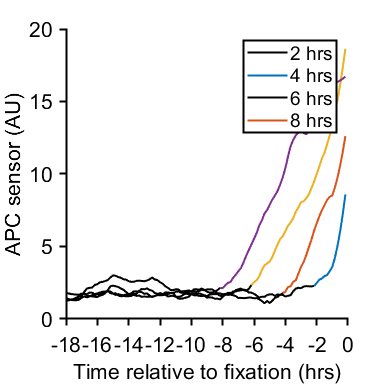

rng(1)
cond=2;
poiAlign = 2;
alignNames = {'APC off'};
times = [2 4 6 8];
cols = lines(length(times));
figure('Units', 'Inches', 'Position', [0, 0, 4, 4]);
hold on
for i=1:length(times)
    inds = (numFrames - S(cond).POI(:,poiAlign)) == times(i)*framesPerHr & S(cond).YFP > 2^PCNAThresh(2) & S(cond).traceStats(:,1) == 1;
    cells = find(inds);
    for numcell = randsample(cells,min([1 length(cells)]))'
        trace = nansmoothm(S(cond).apcNuc(numcell,:),11,'sgolay');
        POI = S(cond).POI(numcell,2);
        reverse_time = -(numFrames/framesPerHr - xTime);
        plot(reverse_time(1:S(cond).POI(numcell,poiAlign)), trace(1:POI),'k','LineWidth',1.5);
        plot(reverse_time(POI:end),trace(POI:end),'Color',cols(i,:),'LineWidth',1.5);
    end
end
hold off
ylabel('APC sensor (AU)');
xlabel('Time relative to fixation (hrs)');
xlim([-18 0]);
xticks([-18:2:0])
%         xlim([0 8]);
legend({'2 hrs','4 hrs','6 hrs','8 hrs'})
print_pdf([pwd() '\Figs\comp_example_traces.pdf'])

**EdU and PCNA time since apc**

conds=[2 1];
poiAligned=2;
offset=0;
f1 = figure('Units', 'Inches', 'Position', [0, 0, 4, 4]);
hold on


gateVals = {{'YFP'},{'YFP'},{'YFP'}};
rangeVals = {{[2^PCNAThresh(2) 10000]}, {[2^PCNAThresh(2) 10000]}, {[2^PCNAThresh(2) 10000]}};

% range = linspace(0,4,10);
%  range = (0:.25:10);
% midpoints = range + (range(2) -range(1))/2;

for i=1:length(conds)
    if i == 2
        %ind = S(conds(i)).sigExpress;
        ind = S(conds(i)).sigMax> 100 & S(conds(i)).sigMax <200; %& S(conds(i)).sigNuc(:,end) < 10;
    elseif i == 3
        ind = max(S(conds(i)).sigNuc,[],2) < 10;    
    else
        ind=~isnan(S(conds(i)).POI(:,poiAligned));
    end
    
    xdata=(numFrames-(S(conds(i)).POI(ind,poiAligned)-offset))/framesPerHr;
    ydata1=log2(abs(S(conds(i)).sigNuc(ind,end)));
    ydata2=log2(S(conds(i)).YFP(ind));
    ydata3=log2(S(conds(i)).FarRed(ind)) ;
    
    gates = gateVals{i};
    inds = true(length(xdata),1) & xdata <=8;
    for j=1:length(gates)
        gateData = S(conds(i)).(gates{j})(ind);
        inds = inds & gateData < rangeVals{i}{j}(2) & gateData > rangeVals{i}{j}(1);

    end
    xdata = xdata(inds);
    ydata1 = ydata1(inds);
    ydata2 = ydata2(inds);
    ydata3 = ydata3(inds);
    
    %numbins = 20;
    %range = linspace(min(xdata),max(xdata),numbins);
%     range= sort(unique(xdata(~isnan(xdata))));
%     range = range(1:2:end);
    range = 0:3/framesPerHr:8;
    xpoints = 0:1/framesPerHr:8;
    [~,~,bin] = histcounts(xpoints,range);
    midpoints = splitapply(@median,xpoints,bin);
%     midpoints = midpoints(1:end-1);
%     midpoints = range + (range(2) -range(1))/2 -1/framesPerHr;
%     midpoints = range;
%     midpoints = range + .5/framesPerHr;
    
    [n,edges,bins]=histcounts(xdata,range);
    binmed=NaN*ones(length(n),3);
    binmean=NaN*ones(length(n),3);
    binperc=NaN*ones(length(n),3);
    binstd=NaN*ones(length(n),3);
    bin25 =NaN*ones(length(n),3);
    bin75 =NaN*ones(length(n),3);
    binmedboot =NaN*ones(length(n),3);
    nums = [];
    for j = 1:(length(n))
        index=bins==j;
        if sum(index) > 5
        binmed(j,1)=median(ydata1(index));
        binmean(j,1)=mean(ydata1(index));
        binperc(j,1)=sum(ydata1(index)<10)/length(ydata1(index));
        binstd(j,1)=std(ydata1(index))/sqrt(length(ydata1(bins==j)));
        
        binmed(j,2)=median(ydata2(index));
        binmean(j,2)=mean(ydata2(index));
        binperc(j,2)=sum(ydata2(index)>PCNAThresh(2))/length(ydata2(index));
        binstd(j,2)=std(ydata2(index))/sqrt(length(ydata2(bins==j)));
        
        binmed(j,3)=median(ydata3(index));
        binmean(j,3)=mean(ydata3(index));
        binperc(j,3)=sum(ydata3(index)>EdUThresh(2))/length(ydata3(index));
        binstd(j,3)=std(ydata3(index))/sqrt(length(ydata3(bins==j)));
        boot = bootstrp(1000,@(x) nanmedian(x) -  binmed(j,3),ydata3(index));
%         boot = bootstrp(1000,@(x) nanmedian(x),ydata3(index));

        bin25(j,3)=prctile(boot,2.5);
        bin75(j,3)=prctile(boot,97.5);
        
        nums(j) = sum(index);
        end
    end
    nums
    min(nums (nums > 0))
%     bounds = [binmed(:,3)-bin25(:,3) bin75(:,3)-binmed(:,3)];
    bounds = [-bin25(:,3) bin75(:,3)];
    subinds = randsample(length(xdata),5000);
    
    
    figure(f1)
    hold on
    errorbar(midpoints,binmed(:,3),bounds(:,1),bounds(:,2),'LineWidth',1.5);
%     errorbar(midpoints,binmean(:,3),binstd(:,3),'LineWidth',1 )
    xlabel('Time since  APC off(hrs)');
    ylabel('log2(EdU) (AU)');    
    h=hline(EdUThresh,'k--');
    ylim([4.5 14.5]); 
    xlim([0 8]);
    axis square
%    hold off
    cells = length(xdata)
end

nums =            0           0         786        1084        1354        1632        1590        1670        1700        1798        1711        1403        1270        1019         717         633


ans = 633

cells = 18367

nums =      0     0   305   532   725   919   804   750   673   613   530   397   320   181   128    93


ans = 93

cells = 6970

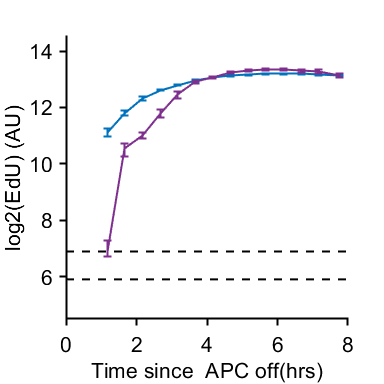

    print_pdf([pwd() '\Figs\comp_scatter_' num2str(conds(i)) '.pdf'])

**PCNA vs EdU**

rng(1)
conds=[1 2];
f = [];
xval = 'YFP';
yval = 'FarRed';
subs = [3000 2000];
style ='-:';
for i = 1:length(conds)
    condition = conds(i);
    % tdata=(numFrames-(S(conds(i)).POI(:,1)))/framesPerHr;
    xdata = ((S(condition).(xval)));
    ydata =  ((S(condition).(yval)));
    cdata = (S(condition).sigNuc(:,end));
    
    xdata(xdata<0) =1;
    ydata(ydata<0) = 1;
    cdata(cdata<0) = 1;
    
    xdata = log2(xdata);
    ydata = log2(ydata);
    cdata = log2(cdata);
    
    inds = S(condition).dna < 2^22 & S(condition).dna > 2^21;
    if condition == 1
        inds = inds & max(S(conds(i)).sigNuc,[],2) > 100;% & tdata < 3 ;
    end
    xdata = xdata(inds);
    ydata = ydata(inds);
    cdata = cdata(inds);
    
         edges = prctile(xdata,5:1:95);
    [binData, edges] = bin_xy(xdata, ydata, {'mean','median','std'},...
        'Edges',edges);
    midpoints = edges;
    midpoints = (midpoints(1:end-1) + midpoints(2:end))/2 ;
    
    inds = randsample(length(xdata),subs(i));
    xdata = xdata(inds);
    ydata = ydata(inds);
    cdata = cdata(inds);
    
    
    if i == 2
        figure(f(1));       
        hold on
        patchline(midpoints(binData(1).numCells > 5),binData(1).median(binData(1).numCells > 5),'linestyle',':','LineWidth',3,'EdgeAlpha',.4)

    end
    
    f(i) = figure('Units', 'Inches', 'Position', [0, 0, 4, 4]);
    hold on
    
%     mapc = gray;
%     mapc(:,[1 3]) = 0;
%     colormap(mapc)
colormap('viridis')
% colormap('parula')
    scatter(xdata,ydata,15,cdata,'filled','MarkerFaceAlpha',.5);
    patchline(midpoints(binData(1).numCells > 5),binData(1).median(binData(1).numCells > 5),'linestyle',style(i),'LineWidth',3,'EdgeAlpha',.4)
    caxis([4 8])
    ylabel(yval);xlabel(xval);
    title(conditions{condition,1});
    ylim([4 14]);
    xlim([5 13]);
    vline(PCNAThresh(2),'k--')
    hline(EdUThresh(2),'k--')
    set(gca,'Color',[.8 .8 .8])
    box on
    axis square
    cells = length(xdata)
    ylabel('log2(EdU) (AU)')
    xlabel('log2(chromatin-bound PCNA) (AU)')
    set(gcf, 'InvertHardcopy', 'off')

%     print_pdf([pwd() '\Figs\pcna_vs_edu_' num2str(condition) '.pdf'])
end

cells = 3000

cells = 2000

**look at traces**

Gate for early mitosis, first .3 hrs, high/low geminin

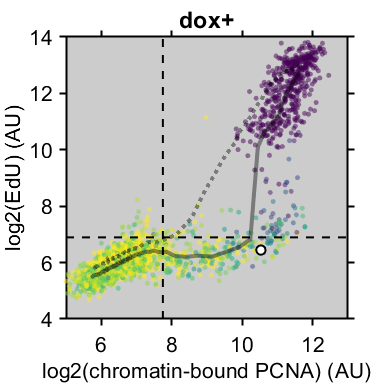

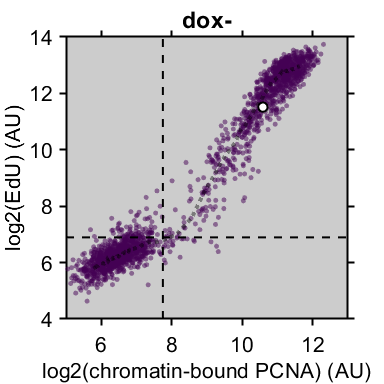

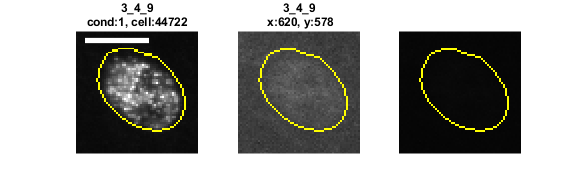

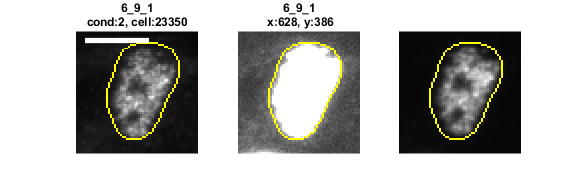

conds=[1 2];
sizeBox = 30;
max_cells = 10;
rng(1)
range1 = [0 5000];
range2 = [0 8000];
pixel_size = .625/2; %um/pixel
bar_length = 10/pixel_size;
exclude = {[],[]};
include = {[44722],[23350],[54214]};
pcna_lim = [10.5 10.6];
edu_lim = [6.1 6.2];

for i = 1:length(conds)
    cond = conds(i);
    ind = S(cond).POI(:,2) > numFrames - 2*framesPerHr & S(cond).dna < 2^22 & S(cond).dna > 2^21 & S(cond).YFP > 2^pcna_lim(1) & S(cond).YFP < 2^pcna_lim(2);
    if i == 1
        ind = ind &  max(S(cond).sigNuc,[],2) > 100 & S(cond).FarRed < 2^EdUThresh(2) & S(cond).FarRed > 2^EdUThresh(1);
    end
    
    if isempty(include{i})
        cells = find(ind);
        cells = cells(~ismember(cells,exclude{cond}));
        num_cells = min([max_cells length(cells)]);
        rsamp = randsample(length(cells),num_cells);
        cells = cells(rsamp);
    else
        cells = include{i};
    end
    
    for j = 1:length(cells)
        c = cells(j);
        shot = [num2str(S(cond).fixedRow(c)),'_',num2str(S(cond).fixedCol(c)),'_',num2str(S(cond).fixedSite(c))];
        x = (S(cond).x(c))/1;
        y = (S(cond).y(c))/1;
        
        im1=imread([impath shot '\' shot '_mask.tif']);
        im2=imread([impath shot '\' shot '_YFP_1.tif']);
        im3=imread([impath shot '\' shot '_FarRed_1.tif']);
        
%         im1_fill = imfill(im1,'holes');
%         im1_label = bwlabel(im1_fill);
%         cell_label = im1_label(round(y),round(x));
%         cell_mask = im1_label == cell_label;
%         cell_bord = imdilate(cell_mask,strel('disk',1)) - imerode(cell_mask,strel('disk',1));
  
        cropx = x + [-sizeBox sizeBox];
        cropx = round(min(max(cropx,0),size(im2,1)));
        xmin = cropx(1);
        width = cropx(2) - cropx(1);
        cropy = y + [-sizeBox sizeBox];
        cropy = round(min(max(cropy,0),size(im2,2)));
        ymin=cropy(1);
        height = cropy(2) - cropy(1);
        im1crop= imcrop(im1,[xmin ymin width height]);
        im2crop= imcrop(im2,[xmin ymin width height]);
        im3crop= imcrop(im3,[xmin ymin width height]);
%         cell_crop = imcrop(cell_bord,[xmin ymin width height]);
        
        figure('units','inches','Position',[0 0 3*2 2])
        subplot(1,3,1)
        b = mat2gray(im2crop,range1);
        b = imoverlay(b,im1crop,'yellow');
%         b = imoverlay(b,cell_crop,'yellow');
        imshow(b);
        hold on
        axis off
        axis square
         t=title({shot, ['cond:' num2str(cond) ', cell:' num2str(c)]},'FontSize',8);
        set(t,'interpreter','none');
        set(gca,'FontSize',8)

        plot([5 ,5  +  bar_length], [5, 5 ],'Color','w','LineWidth',4)
        
        imwrite(b,[pwd() '\Figs\PCNA_images_cond_' num2str(cond) 'cell_' num2str(c) '.tiff'])
        
        subplot(1,3,2)
        b = mat2gray(im3crop,range2/10);
        b = imoverlay(b,im1crop,'yellow');
%         b = imoverlay(b,cell_crop,'yellow');
        imshow(b);
        hold on
        axis off
        axis square
        t=title({shot, [' x:' num2str(round(x)) ', y:' num2str(round(y))]},'FontSize',8);
%         t=title(sprintf('cond: %d, cell: %d, %.1f min',cond,c,dat(cond).POI_time(c,poi_align)*60));
        set(gca,'FontSize',8)
        set(t,'interpreter','none');
         
        subplot(1,3,3)
        b = mat2gray(im3crop,range2);
        b = imoverlay(b,im1crop,'yellow');
%         b = imoverlay(b,cell_crop,'yellow');
        imshow(b);
        hold on
        axis off
        axis square
        
        imwrite(b,[pwd() '\Figs\EdU_images_cond_' num2str(cond) 'cell_' num2str(c) '.tiff'])

        
        print_pdf([pwd() '\Figs\images_cond_' num2str(cond) 'cell_' num2str(c) '.pdf'])
       
        figure(f(cond))
        hold on
        scatter(log2(S(cond).YFP(c)), log2(S(cond).FarRed(c)),50,'k','LineWidth',1.5,'MarkerFaceColor','w')
        print_pdf([pwd() '\Figs\pcna_vs_edu_' num2str(cond) '.pdf'])

    end

end    

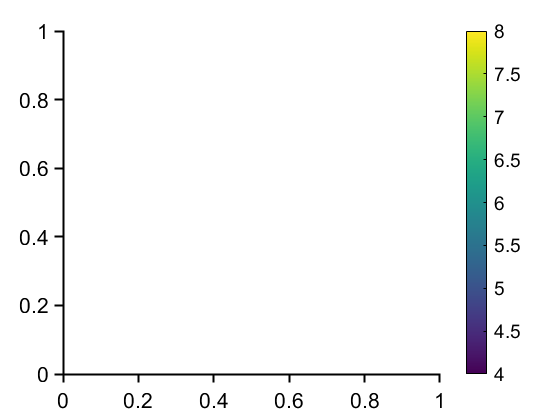

figure,
colormap('viridis')
caxis([4 8])
colorbar
print_pdf([pwd() '\Figs\pcna_vs_edu_' num2str(condition) 'colorbar.pdf'])